## PARAMETER EFFECT ANALYSIS

## Road Profile - Generation

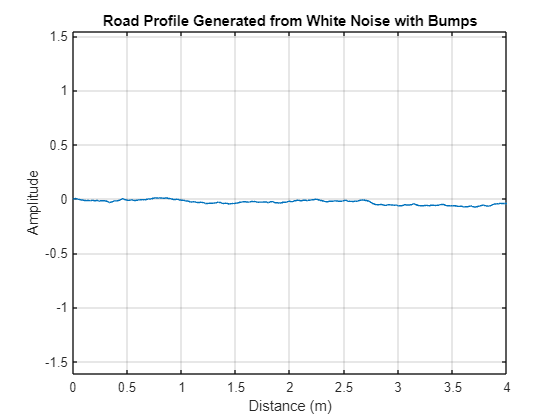

% [X_r, Z_r] = bump_road_input(5,0.12,15);

profile_length = 200;       % Length of the road profile (meters)
sampling_rate = 50;        % Numberof points per meter
amplitude_factor = 0.005;     % Roughness
num_bumps = 5;             % Number of bumps
bump_amplitude = 0.001;       % Amplitude of bumps
bump_frequency = 0.5;       % Frequency of bumps

[X_r, Z_r] = generateRoadProfileWithBumps(profile_length, sampling_rate, amplitude_factor, num_bumps, bump_amplitude, bump_frequency);

road.X_r = X_r;
road.Z_r = Z_r;

## Car Model

%Vehicle
scooter.mass = 150;    
scooter.front_unsprung_mass = 15;       
scooter.rear_unsprung_mass = 15;    
scooter.Lateral_MOI = 40;    
scooter.CG_2_Front = 0.5;      
scooter.CG_2_Rear = 0.5;    

stiffness.front_strut = 15000;  
stiffness.rear_strut = 15000;   
stiffness.tire_front = 44000;
stiffness.tire_rear = 44000;

damping.strut_front = 1000;
damping.strut_rear = 1000;

%Velocity
initial_vel = 10; %velocity in m/s
acc  = 0;

## Stiffness Variation

% Stiffness variation from 200 to 30000 
% Damping kept at 1000 for analysis
k = 200:100:30000;
rms_acc = k;
natural_frequency = [k;k];
rms_pitch = k;
TRS = k;
Total_POW = k;

Simulating

for i = 1:length(k)
    
    stiffness.front_strut = k(i);  
    stiffness.rear_strut = k(i);  
    [displacement, velocity, acceleration] = Ride_Comfort_Analysis(scooter, stiffness, damping, road, initial_vel, acc);
    rms_acc(i) = rms(acceleration.a_body);
    rms_pitch(i) = rms(acceleration.a_theta);
    TRS(i) = max(acceleration.a_body)/max(acceleration.a_unsprung_front);

    [Weighted_PSD, frequency_arr, PSD] = Frequency_analysis(acceleration.a_body,acceleration.time);
    Total_POW(i) = trapz(frequency_arr, PSD);

    peaks = [];
    locs = [];  
    for j = 2:length(frequency_arr)-1
        if PSD(j) > PSD(j-1) && PSD(j) > PSD(j+1)
            peaks = [peaks, PSD(j)];
            locs = [locs, frequency_arr(j)];
        end
    end    
    
    natural_frequency(:,i) = (locs(1:2))';

end

## Plotting

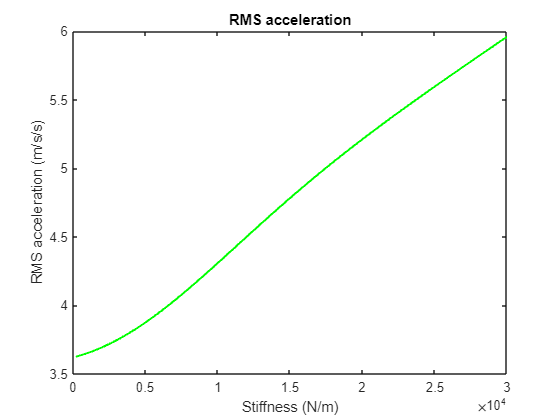

plot(k, rms_acc, 'g', 'LineWidth', 1.5);
xlabel('Stiffness (N/m)');
ylabel('RMS acceleration (m/s/s)');
title('RMS acceleration');

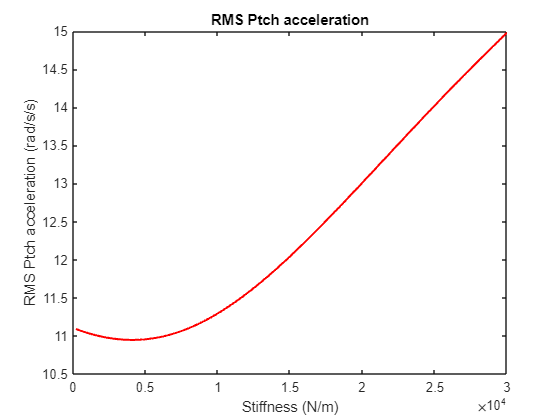


plot(k, rms_pitch, 'r', 'LineWidth', 1.5);
xlabel('Stiffness (N/m)');
ylabel('RMS Ptch acceleration (rad/s/s)');
title('RMS Ptch acceleration');

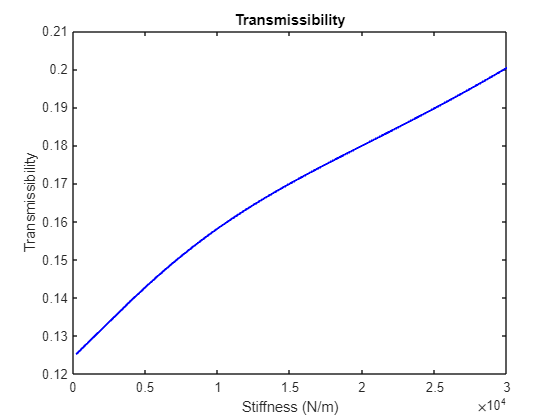


plot(k, TRS, 'b', 'LineWidth', 1.5);
xlabel('Stiffness (N/m)');
ylabel('Transmissibility');
title('Transmissibility');

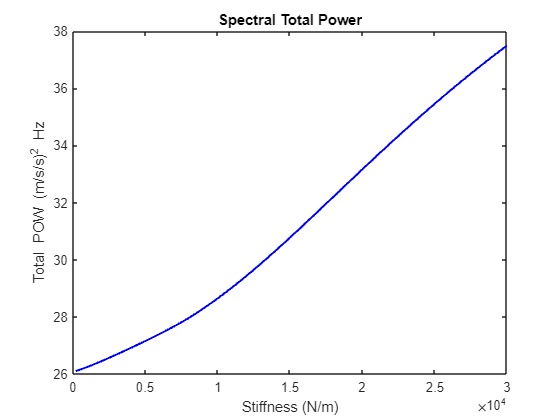


plot(k, Total_POW, 'b', 'LineWidth', 1.5);
xlabel('Stiffness (N/m)');
ylabel('Total POW (m/s/s)^2 Hz');
title('Spectral Total Power');

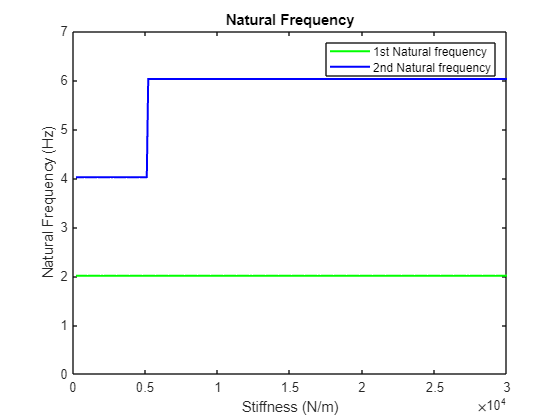


plot(k, natural_frequency(1,:), 'g', 'LineWidth', 1.5);
hold on;
plot(k, natural_frequency(2,:), 'b', 'LineWidth', 1.5);
xlabel('Stiffness (N/m)');
ylabel('Natural Frequency (Hz)');
legend('1st Natural frequency', '2nd Natural frequency');
title('Natural Frequency');
ylim([0 7])
hold off

##  Damping Variation

% Stiffness kept at 15000 for analysis
C = 0:100:10000;
rms_acc = C;
natural_frequency = [C;C];
stiffness.front_strut = 15000;  
stiffness.rear_strut = 15000;   

rms_pitch = C;
TRS = C;
Total_POW = C;

Simulating

for i = 1:length(C)
    
    damping.strut_front = C(i);
    damping.strut_rear = C(i);
    [displacement, velocity, acceleration] = Ride_Comfort_Analysis(scooter, stiffness, damping, road, initial_vel, acc);
    rms_acc(i) = rms(acceleration.a_body);
    rms_pitch(i) = rms(acceleration.a_theta);
    TRS(i) = max(acceleration.a_body)/max(acceleration.a_unsprung_front);

    [Weighted_PSD, frequency_arr, PSD] = Frequency_analysis(acceleration.a_body,acceleration.time);
    Total_POW(i) = trapz(frequency_arr, PSD);

    peaks = [];
    locs = [];  
    for j = 2:length(frequency_arr)-1
        if PSD(j) > PSD(j-1) && PSD(j) > PSD(j+1)
            peaks = [peaks, PSD(j)];
            locs = [locs, frequency_arr(j)];
        end
    end    
    [peaks,sortIdx] = sort(peaks,'descend');
    locs = locs(sortIdx);

    natural_frequency(:,i) = (locs(1:2))';

end

## Plotting

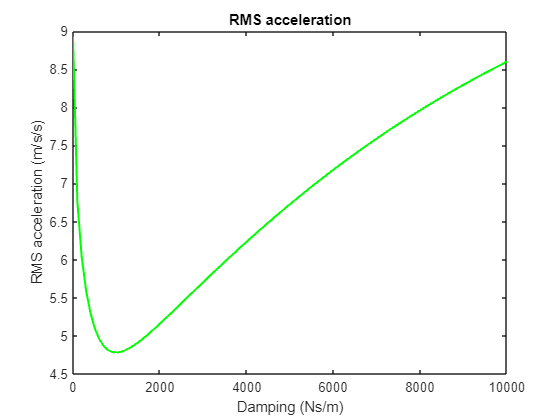

plot(C, rms_acc, 'g', 'LineWidth', 1.5);
xlabel('Damping (Ns/m)');
ylabel('RMS acceleration (m/s/s)');
title('RMS acceleration');

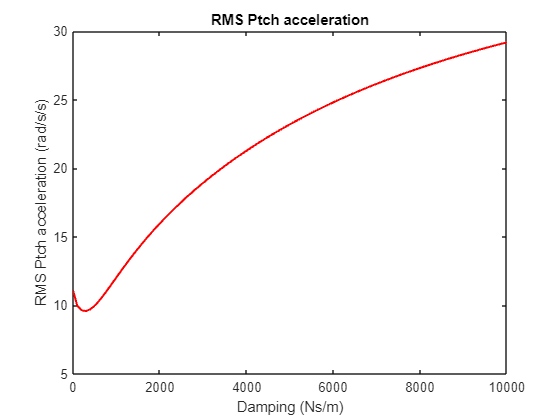


plot(C, rms_pitch, 'r', 'LineWidth', 1.5);
xlabel('Damping (Ns/m)');
ylabel('RMS Ptch acceleration (rad/s/s)');
title('RMS Ptch acceleration');

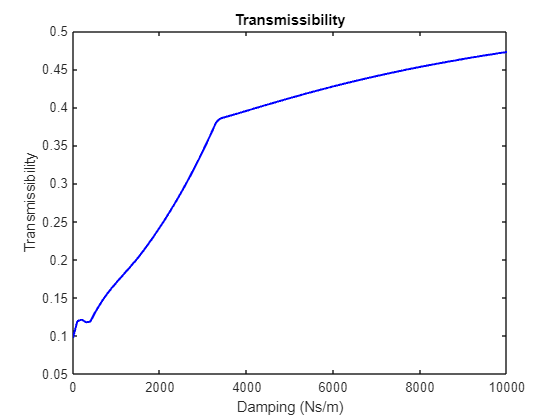


plot(C, TRS, 'b', 'LineWidth', 1.5);
xlabel('Damping (Ns/m)');
ylabel('Transmissibility');
title('Transmissibility');

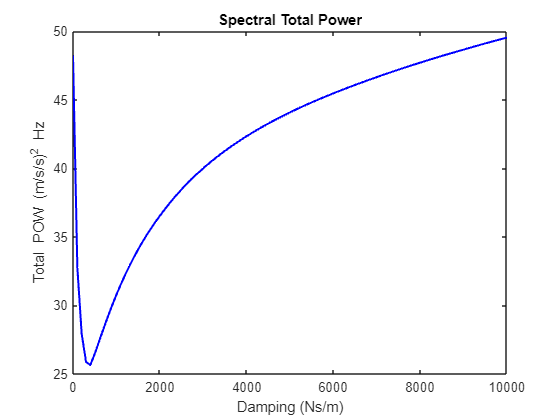


plot(C, Total_POW, 'b', 'LineWidth', 1.5);
xlabel('Damping (Ns/m)');
ylabel('Total POW (m/s/s)^2 Hz');
title('Spectral Total Power');

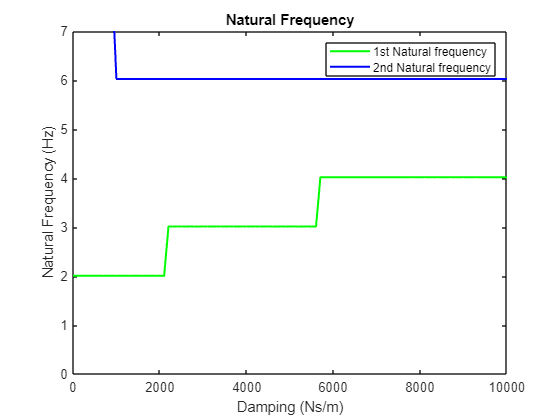


plot(C, natural_frequency(1,:), 'g', 'LineWidth', 1.5);
hold on;
plot(C, natural_frequency(2,:), 'b', 'LineWidth', 1.5);
xlabel('Damping (Ns/m)');
ylabel('Natural Frequency (Hz)');
legend('1st Natural frequency', '2nd Natural frequency');
title('Natural Frequency');
ylim([0 7])
hold off